## EXERCISE 1

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear all; close all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

syms x y

fx = -x + 0.08*y + x^2*y

$$fx = y\,x^{2}-x+\frac{2\,y}{25}$$

fy = 0.6 - 0.08*y -x^2*y

$$fy = -y\,x^{2}-\frac{2\,y}{25}+\frac{3}{5}$$

% setting the matlab function for our system
f_lmb = @(t,z) [-z(1) + 0.08*z(2) + (z(1))^2 * z(2);0.6 - 0.08*z(2) - (z(1)^2) * z(2)];

a)

% CALCULATE THE FIXED POINTS
fixPts = solve([fx; fy], [x; y])

fixPts = struct with fields:
    x: 3/5
    y: 15/11


fixPts = double([fixPts.x'; fixPts.y'])

fixPts =     0.6000
    1.3636


b)

% Computing the jacobian matrix and the eigenvalues for the fixed points
JacFixPts = zeros(2, 2, size(fixPts, 2));
eigenvalues = zeros(size(fixPts, 2), 2);

for k = 1:size(fixPts, 2)
    JacFixPts(:,:,k) = double(subs(jacobian([fx, fy], [x, y]), {x, y}, {fixPts(1, k), fixPts(2, k)}));
    eigenvalues(k, :) = eig(JacFixPts(:,:,k));
end

% IDENTIFY AND CLASSIFY THE FIXED POINTS: HYPERBOLIC VS NON-HYPERBOLIC
for k =1:size(fixPts, 2)
    if all(real(eigenvalues(k, :)) ~= 0)
        fprintf('Fixed point at (%f, %f) is hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    else
        fprintf('Fixed point at (%f, %f) is not hyperbolic.\n', fixPts(1, k), fixPts(2, k));
    end
end

Fixed point at (0.600000, 1.363636) is hyperbolic.



% Represent the fixed points
h1 = figure;
hold on;
grid on;
fpts = plot(fixPts(1,:), fixPts(2,:), 'o', 'MarkerFaceColor', 'r');

c)

% 3. COMPUTE THE NULLCLINES
% with respect y
xcline_y = solve(fx == 0, y);
ycline_y = solve(fy == 0, y);

% Representing the nullclines
nullX = fimplicit(fx, [-eps 5 -eps 5], 'r--', 'LineWidth', 1.5);
nullY = fimplicit(fy, [-eps 5 -eps 5], 'g--', 'LineWidth', 1.5);

e)

% REPRESENT FLOW IN A GRID 10X10
% Campo vectorial
N = 10; % tamaño de la cuadrícula
xlin = linspace(0, 5, N);
ylin = linspace(0, 5, N);
[Xgrid, Ygrid] = meshgrid(xlin, ylin);

fx_grid = subs(fx, [x, y], {Xgrid, Ygrid});
fy_grid = subs(fy, [x, y], {Xgrid, Ygrid});

magnitude = sqrt(fx_grid.^2 + fy_grid.^2);
fx_normalized = fx_grid ./ magnitude;
fy_normalized = fy_grid ./ magnitude;

flow = quiver(Xgrid, Ygrid, fx_normalized, fy_normalized, 'AutoScale', 'on', 'AutoScaleFactor', 0.25, 'Color', 'k');

axis([-eps 3.5 -eps 3.5]);
xlabel('x');
ylabel('y');
title('Campo vectorial con puntos fijos, eigenvalores y nullclines');

d) y g)

% REPRESENT TRAJECTORY INITIALIZED AT (0.5, 0.5)
y0 = [0.5 0.5]

y0 =     0.5000    0.5000


t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj = plot(ys(:,1),ys(:,2),'b-'); plot(y0(1),y0(2),'o','MarkerFaceColor','b');

% REPRESENT AN  UPWARD RADIUS PATH
y0 = [0.5 2]

y0 =     0.5000    2.0000


t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj1 = plot(ys(:,1),ys(:,2),'m-'); plot(y0(1),y0(2),'o','MarkerFaceColor','m');

% REPRESENT A DOWNWARD RADIUS PATH
y0 = [2 2]

y0 =      2     2


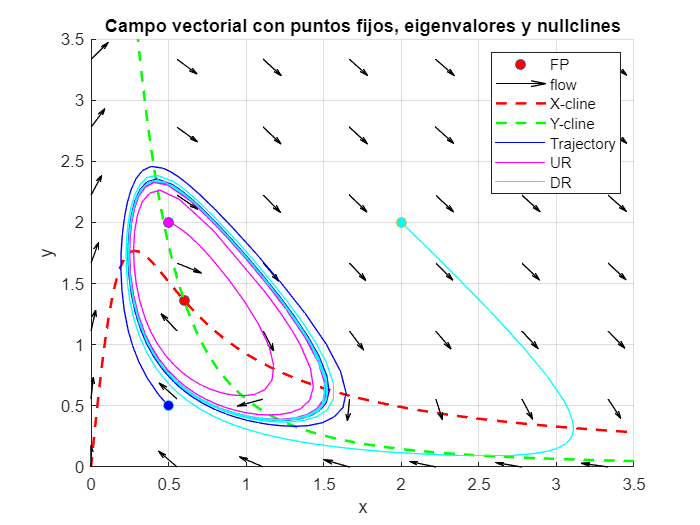

t0 = 0.5; tf = 50;
tspam = [t0,tf];
[ts,ys] = ode45(f_lmb,tspam, y0);
traj2 = plot(ys(:,1),ys(:,2),'cyan-'); plot(y0(1),y0(2),'o','MarkerFaceColor','cyan');

legend([fpts flow nullX nullY traj traj1 traj2],{'FP', 'flow', 'X-cline', 'Y-cline', 'Trajectory', 'UR', 'DR'},'Location', 'NorthEast')


disp('As it can be seen in the phase diagram, this system has a limit cycle')

As it can be seen in the phase diagram, this system has a limit cycle


disp('FP - Fixed Point')

FP - Fixed Point


disp('UR - Upaward Radius Trajectory')

UR - Upaward Radius Trajectory


disp('DR - Downward Radius trajectory')

DR - Downward Radius trajectory
